%interruption generation
X = zeros(200,1280);
%X(2,:) = (1+a*(u(t-0.12)-u(t-0.22))).*x;
%X(1,:) = (1+a*(u(t-t1)-u(t-t2))).*x;

i = 1;
%for i = 1:200
    for a = 0.9:0.01:1     % alpha parameter
        for d = 0.04:0.07:0.35     %duration of disturbance
            for t2 = 0.15:0.05:0.35    %ending time stamp of disturbance
                t = 0:0.0003125:0.4-0.0003125;
                A = 1;
                %a = 0.2;
                f = 50;
                w = 2*pi*f;
                x = A*sin(w.*t);
                u = inline('t>=0');
                t1 = t2 - d;
                X(i,:) = (1+a*(u(t-t1)-u(t-t2))).*x;
                i = i+1;
            end
        end
    end
%end

X

X =          0    0.0980    0.1951    0.2903    0.3827    0.4714    0.5556    0.6344    0.7071    0.7730    0.8315    0.8819    0.9239    0.9569    0.9808    0.9952    1.0000    0.9952    0.9808    0.9569    0.9239    0.8819    0.8315    0.7730    0.7071    0.6344    0.5556    0.4714    0.3827    0.2903    0.1951    0.0980    0.0000   -0.0980   -0.1951   -0.2903   -0.3827   -0.4714   -0.5556   -0.6344   -0.7071   -0.7730   -0.8315   -0.8819   -0.9239   -0.9569   -0.9808   -0.9952   -1.0000   -0.9952
         0    0.0980    0.1951    0.2903    0.3827    0.4714    0.5556    0.6344    0.7071    0.7730    0.8315    0.8819    0.9239    0.9569    0.9808    0.9952    1.0000    0.9952    0.9808    0.9569    0.9239    0.8819    0.8315    0.7730    0.7071    0.6344    0.5556    0.4714    0.3827    0.2903    0.1951    0.0980    0.0000   -0.0980   -0.1951   -0.2903   -0.3827   -0.4714   -0.5556   -0.6344   -0.7071   -0.7730   -0.8315   -0.8819   -0.9239   -0.9569   -0.9808   -0.9952   -1.0000   -0

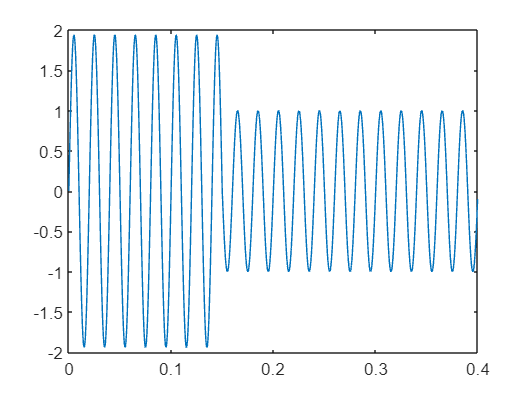

            
plot(t,X(121,:)) 

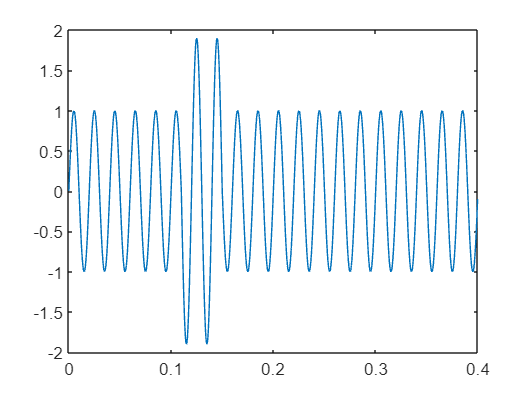

plot(t,X(1,:))

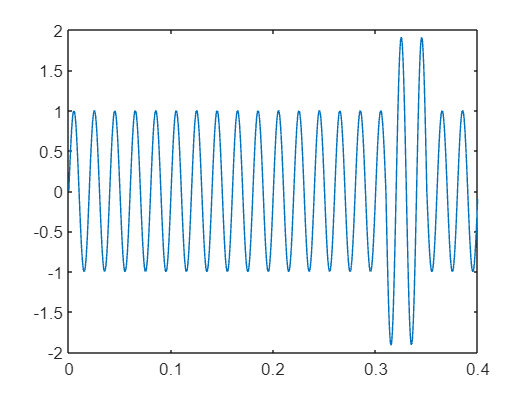

plot(t,X(30,:))

%X(167,:) = (1+a*(u(t-0.12)-u(t-0.22))).*x
%plot(t,x1)
